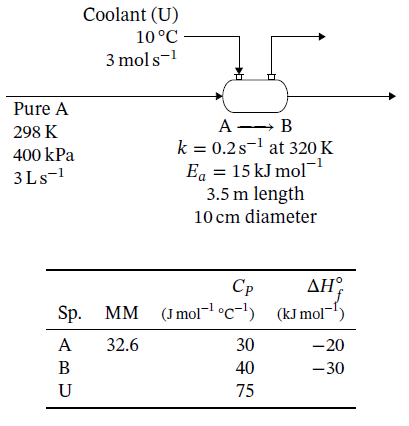

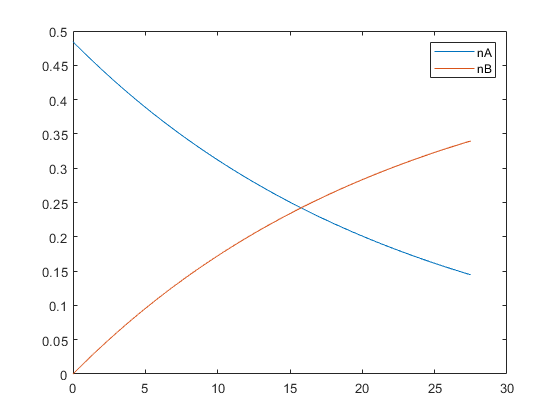

% Isothermal
T0 = 298; % K
P0 = 400; % kPa
v0 = 3; % L/s
nA0 = P0*v0/(8.314*T0); % 8.314 L-kPa/(mol-K)
Vmax = 0.25*pi*(10/100)^2*3.5*1000; % m3 -> L
Y0 = [nA0; 0]; % [nA; nB]
[V, Y] = ode45(@myODE, [0 Vmax], Y0);
plot(V, Y); legend('nA', 'nB');

function dYdV = myODE(V, Y)
nA = Y(1); % mol/s
nB = Y(2); % mol/s
k = 0.2*exp(15000/8.314*(1/320-1/298)); % (3.10)
nT = nA+nB; % mol/s

R = 8.314; % L-kPa/mol-K
T = 298; % K
P = 400; % kPa
v = nT*R*T/P; % IGL: nT*R*T/P, or (5.5)

r = k*nA/v; % mol/L-s, elementary
dnAdV = -r; % mol/L-s, (7.1)
dnBdV = r; % mol/L-s, (7.1)
dYdV = [dnAdV; dnBdV]; % mol/L-s
end